result1 = sqrt(1 + 1i);
result2 = sqrt(-2 + 2i);
z = sqrt(3) + (2 * sqrt(3) - 3) * 1i;
result3 = z^(1/6); 
disp('1):');

1):


disp(result1);

   1.0987 + 0.4551i



disp('2):');

2):


disp(result2);

   0.6436 + 1.5538i



disp('3):');

3):


disp(result3);

   1.1012 + 0.0481i



syms z1 z2
eq1 = z1 + 2*z2 == 1 + 1i;
eq2 = 3*z1 + 1i*z2 == 2 - 3i; 
sol = solve([eq1, eq2], [z1, z2]);
disp('solution of z1:');

solution of z1:


disp(sol.z1);

$$1-\mathrm{i}$$

disp('solution of  z2:');

solution of  z2:


disp(sol.z2);

$$\mathrm{i}$$

syms n; 
limit1 = limit((3 + 4i)/6, n, inf);
limit2 = limit(n + (n^2)/2, n, inf); 
disp('limit 1:');

limit 1:


disp(limit1);

$$\frac{1}{2}+\frac{2}{3}\,\mathrm{i}$$

disp('limit 2:');

limit 2:


disp(limit2);

$$\infty$$

syms z
f = (z^2 - 1) * (z^2 + 1)^2;
derivative = diff(f, z); 
derivative_at_i_over_2 = subs(derivative, z, 1i/2); 
disp('the value of derivate for z = i/2:');

the value of derivate for z = i/2:


disp(derivative_at_i_over_2);

$$-\frac{21}{16}\,\mathrm{i}$$

integral1 = int(1 + tan(z)/cos(z)^2, z, 1, 1i);
integral2 = int((z - 1i) * exp(-z), z, 0, 1i); 
disp('integral 1:');

integral 1:


disp(integral1);

$$-\frac{1}{2\,{\cos\left(1\right)}^{2}}+\frac{1}{2\,{\cos\left(\mathrm{i}\right)}^{2}}-1+\mathrm{i}$$

disp('integral 2:');

integeral 2:


disp(integral2);

$$1-{\mathrm{e}}^{-\mathrm{i}}-\mathrm{i}$$

syms z;
result11 = taylor(sin(3 + z), z, 'Order', 10);
result22 = taylor(exp(z) * log(1 + z), z, 'Order', 10);
result33 = taylor((2*z^5 + 5*z^3 + z^2 + 2) / (z^3 + 2*z^2 + 3*z + 1), z, 'Order', 10);

disp('10 Taylor items of 1):');

10 Taylor items of 1):


disp(result11);

$$\frac{\cos\left(3\right)\,z^{9}}{362880}+\frac{\sin\left(3\right)\,z^{8}}{40320}-\frac{\cos\left(3\right)\,z^{7}}{5040}-\frac{\sin\left(3\right)\,z^{6}}{720}+\frac{\cos\left(3\right)\,z^{5}}{120}+\frac{\sin\left(3\right)\,z^{4}}{24}-\frac{\cos\left(3\right)\,z^{3}}{6}-\frac{\sin\left(3\right)\,z^{2}}{2}+\cos\left(3\right)\,z+\sin\left(3\right)$$

disp('10 Taylor items of 2):');

10 Taylor items of 2):


disp(result22);

$$\frac{629\,z^{9}}{17280}-\frac{29\,z^{8}}{720}+\frac{23\,z^{7}}{504}-\frac{7\,z^{6}}{144}+\frac{3\,z^{5}}{40}+\frac{z^{3}}{3}+\frac{z^{2}}{2}+z$$

disp('10 Taylor items of 3):');

10 Taylor items of 3):


disp(result33);

$$-4417\,z^{9}+1900\,z^{8}-817\,z^{7}+351\,z^{6}-151\,z^{5}+66\,z^{4}-30\,z^{3}+15\,z^{2}-6\,z+2$$

syms z;
f = (1 + z^4) / (z * (z^2 + 1)^2); 
residue = limit(z * f, z, 0);
disp('residue:');

residue:


disp(residue);

$$1$$

t = linspace(0, 2*pi, 100); 
z = exp(1i*t);
functions = (2*z.^2 + 1) ./ (2*z.^3 + z.^2 + 4*z-5);
integral_value = trapz(t, functions);
disp('the value of integral:');

the value of integral:


disp(integral_value);

   0.6117 + 0.0000i



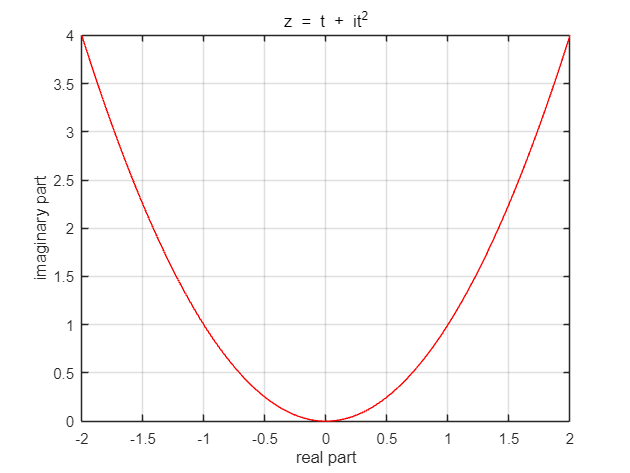

% x axis
t = linspace(-2, 2, 100); 
% section 1
z1 = t + 1i * t.^2;
figure;
plot(real(z1), imag(z1), 'r');
title('z = t + it^2');
xlabel('real part');
ylabel('imaginary part');
grid on;

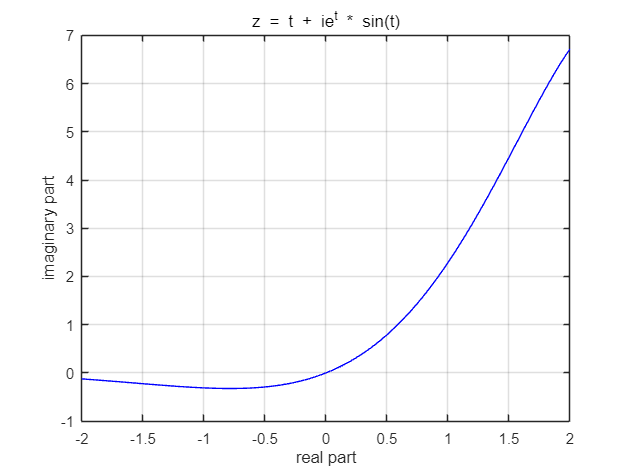

% section 2
z2 = t + 1i * exp(t) .* sin(t);
figure;
plot(real(z2), imag(z2), 'b');
title('z = t + ie^{t} * sin(t)');
xlabel('real part');
ylabel('imaginary part');
grid on;